# Segmentació per clustering. K-means

**Obriu la imatge 'peppers.png':**

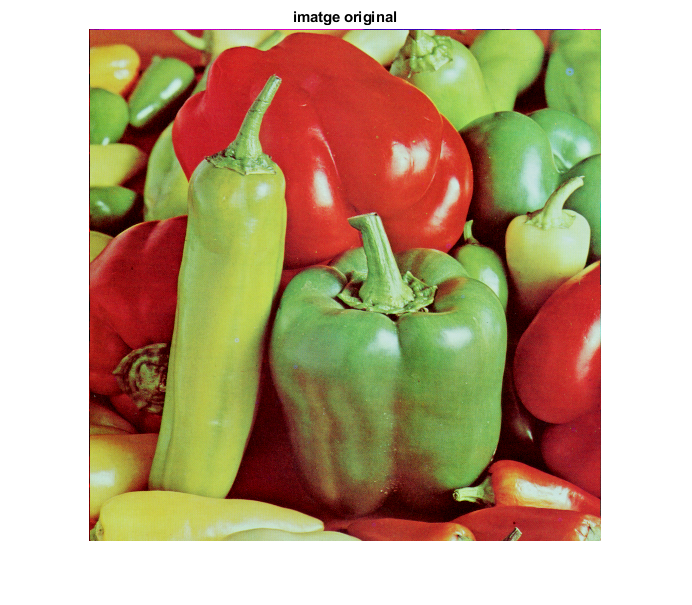

im = imread('peppers.png');
[MAXFILA, MAXCOL, chan]=size(im);
figure,imshow(im),title('imatge original')

La segmentarem per color. Treballarem en l’espai Hue-Sat

hsv=rgb2hsv(im);
hs=hsv(:,:,1:2);
vect=reshape(hs,MAXFILA*MAXCOL,2); % feature vector. 2 features per píxel
Nclusters=3; %vermell, verd, i negre

Usarem la funció kmeans amb distancia citiblock

[cluster_idx, cluster_center] = kmeans(vect,Nclusters,'distance','cityblock');

Obtenim la imatge etiquetada pel número cluster:

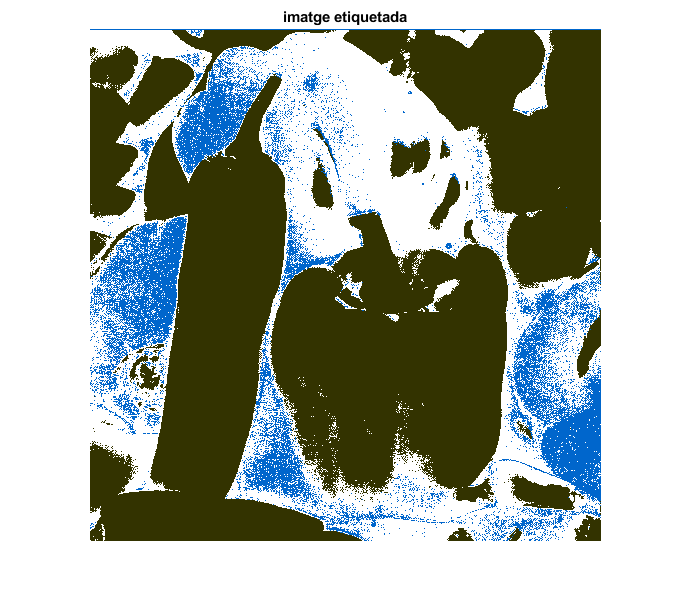

eti=reshape(cluster_idx,MAXFILA,MAXCOL);
figure,imshow(eti,[]),colormap(colorcube), title('imatge etiquetada')

**Algo no va. Els pebrots vermells queden mal segmentats. (COMTE! EL RESULTAT DE KMEANS ÉS SEMPRE DIFERENT. DEPÈN DE L’EXECUCIÓ, EL RESULTAT PODRIA SORTIT MILLOR O PITJOR). Què està passant?**

L'algoritme de k-means es dedica a ajuntar en clusters píxels que es troben a prop, per tant, el k-means no es “capaç” de discernir entre les diferents tonalitats de vermell.

K-means es un algoritme que “separa” píxels per la seva posició, no pel seu “significat”.

% Representem els píxels en l’espai hue-sat
figure,scatter(vect(:,1),vect(:,2),1,cluster_idx);
xlabel('hue');ylabel('Sat')
title('HS space')

**El hue és un angle. És cíclic. Píxels vermells amb hue molt similars queden a banda i banda de l’espai hue-sat per culpa del pas per zero.**

# Exercici

**La funció kmeans implementada a matlab no funciona amb aritmètica cíclica, per tant, les característiques no poden ser angles. Implementeu vosaltres una funció kmeans que pugui treballar amb característiques cícliques:**

Fent recerca per internet he trobat aquesta reprensentació de color ([LAB](https://ca.wikipedia.org/wiki/Espai_de_color_LAB)), semblant a la HSV però que no té el problema de ser cíclica.

Agafant el model anterior, arribem al següent codi:

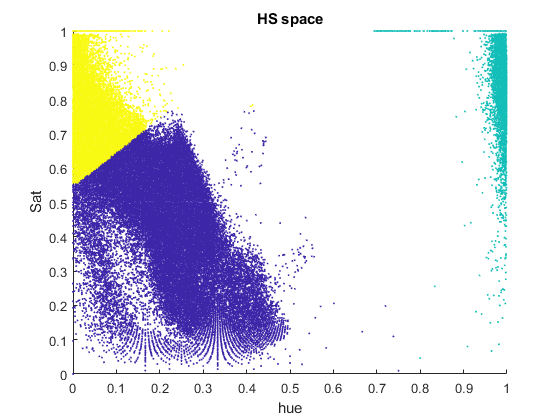

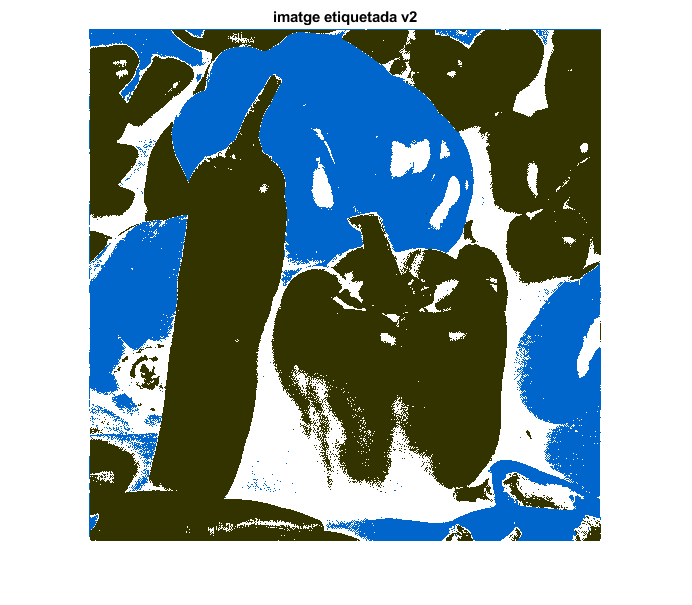

g = rgb2lab(im); %convert rgb a lab (luminositat i A, B)
ab = g(:,:,2:3); %independent de la lluminositat
vect2 = reshape(ab, MAXFILA*MAXCOL,2); %feature vector
[cluster_idx, cluster_center] = kmeans(vect2,Nclusters,'distance','cityblock');
eti2 = reshape(cluster_idx,MAXFILA,MAXCOL);
figure,imshow(eti2,[]),colormap(colorcube), title('imatge etiquetada v2')